Import the csv file ios_act.csv and remove unnecassery columns

ios_act_raw = readtable('ios_act.csv');
%Remove unnecassary columns 
ios_act = removevars(ios_act_raw, [1:4,12,13,17,21,25:47,49,50:54]);
head(ios_act,5) % show first 5 rows of table

Explore the data

activity = ios_act.activity;
automotive = ios_act.activity == 4;
%sum(automotive);
prop = ios_act.Properties;
sum(ismissing(ios_act)); %Check for missing values
%Count the number of the different activities
activitygrp = groupsummary(ios_act,"activity"); 

Preprosess the data

idx = isoutlier(ios_act,"median");
sum(idx);

Analyse the data visually

catlabels = ordinal(categorical(activitygrp.activity));
getlabels(catlabels);
catlabels = setlabels(catlabels,...
    {'Unknown','Stationary','Walking','Running','Automotive'})

barchart = bar(catlabels, activitygrp.GroupCount)
ax = ancestor(barchart, 'axes');
r = ax.YAxis;
r.TickLabelFormat = '%.g';
r.Exponent = 0;
title("Distribution of the target variable activity")
xlabel("Activity");
ylabel("Frequency");

stackedplot(ios_act);

%densityplot(~value|variable,data = ios_act.mlt, scales = 
% list(x = list(relation = "free"), y = list(relation = "free"))
% ,adjust = 1.25, pch = "|", xlab = "Predictor")


Prepare the dataset for training and test

rng(8000,'twister'); %Set the random number generator to a known state

% Define a random (cross-validation) partition on a set of data of a specified size
iosactCVP = cvpartition(size(ios_act,1),'holdout',0.2) %holdout = test set
idx = iosactCVP.test; %test contains 0 for test records and 1 for training records

%seperate to training and test data
dataTrainTmp = ios_act(~idx,:);
dataTest = ios_act(idx,:);

iosactCVP_val = cvpartition(size(dataTrainTmp,1),'holdout',0.2);
idx_val = iosactCVP_val.test;

%seperate to training and test data
dataTrain = ios_act(~idx_val,:);
dataVal = ios_act(idx_val,:);

Prepare the variables 

%Predictors and output variable in the training dataset
XTrain = dataTrain{:,1:16}; %Predictors
YTrain = dataTrain{:,17}; %Output variable

%Predictors and output variable in the test dataset
XVal = dataVal{:,1:16}; %Predictors
YVal = dataVal{:,17}; %Output variable

%Predictors and output variable in the test dataset
XTest = dataTest{:,1:16}; %Predictors
YTest = dataTest{:,17}; %Output variable

%Training 3D input (Total was 61136)
transpDataTrain = transpose(table2array(normalize(array2table(XTrain)))); %Transpose from rows to columns and normalise data
numDataTrain = num2cell(transpDataTrain,1); %Convert into a cell array
matrixDataTrain = reshape((numDataTrain),[],1); %Create a matrix with one column and nrows with a cell containing the predictor values
catTarget = categorical(table2array(array2table(YTrain))); %Array with target variables (classes)

%Validation 3D input
val_transpDataTrain = transpose(table2array(normalize(array2table(XVal)))); %Transpose from rows to columns and normalise data
val_numDataTrain = num2cell(val_transpDataTrain,1); %Convert into a cell array
val_matrixDataTrain = reshape((val_numDataTrain),[],1); %Create a matrix with one column and nrows with a cell containing the predictor values
val_catTarget = categorical(table2array(array2table(YVal))); %Array with target variables (classes)

%Test 3D input
transpDataTest = transpose(table2array(normalize(array2table(XTest)))); %Transpose from rows to columns and normalise data
numDataTest = num2cell(transpDataTest,1); %Convert into a cell array
matrixDataTest = reshape((numDataTest),[],1); %Create a matrix with one column and nrows with a cell containing the predictor values
catTargetTest = categorical(table2array(array2table(YTest))); %Array with target variables (classes)



Prepare the hyper-parameters for the neural net


numFeatures = 16; %Number of predictors
%The number of hidden units corresponds to the amount of information
%remembered between time steps (the hidden state). The hidden state
%can contain information from all previous time steps, regardless 
%of the sequence length
numHiddenUnits = 100; %Increased from 100. Neurons
numClasses = 5; %Number of output classes

% The sequence input layer inputs sequence data to a network.
% The input size is set to the number of predictors

% The LTSM layer learns long-term dependencies between time
% steps in time series and sequence data. The number of hidden
% units corresponds to the amount of information remembered
% between time steps (the hidden state)
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

layers_2 = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    dropoutLayer(0.2)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    dropoutLayer(0.2)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

miniBatchSize = 27;

%options = trainingOptions('adam', ...
%    'ExecutionEnvironment','cpu', ...
%    'MaxEpochs',60, ...   %60 original
%    'GradientThreshold',1, ...
%    'InitialLearnRate',3e-4, ...
%    'SquaredGradientDecayFactor',0.99, ...
%    'MiniBatchSize',miniBatchSize, ...
%    'SequenceLength','longest', ...
%    'ValidationData', {val_matrixDataTrain,val_catTarget}, ...
%    'Shuffle','never', ...
%    'Verbose',0, ...
%    'ValidationFrequency',30, ...
%    'Plots','training-progress');

options = trainingOptions('adam', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'ValidationData', {val_matrixDataTrain,val_catTarget}, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

optionsSGDM = trainingOptions('sgdm', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'ValidationData', {val_matrixDataTrain,val_catTarget}, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

optionsRSMP = trainingOptions('rmsprop', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'ValidationData', {val_matrixDataTrain,val_catTarget}, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

optionsSGDM = trainingOptions('sgdm', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'ValidationData', {val_matrixDataTrain,val_catTarget}, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',1, ...
    'Plots','training-progress');

% 'ValidationData', {val_matrixDataTrain,val_catTarget}, ...

Hyper-paramerts for optimisation

[https://se.mathworks.com/help/deeplearning/ug/deep-learning-using-bayesian-optimization.html.](https://se.mathworks.com/help/deeplearning/ug/deep-learning-using-bayesian-optimization.html.) Training and validation data are inputs

optVars = [
    optimizableVariable('MaxEpochs',[10 20],'Type','integer')
    optimizableVariable('InitialLearnRate',[1e-2 1],'Transform','log')
    optimizableVariable('hiddenLayerSize',[50 200],'Type','integer')
    optimizableVariable('MiniBatchSize',[5 40],'Type','integer')
   ];


ObjFcn = makeObjFcn(matrixDataTrain,catTarget,val_matrixDataTrain,val_catTarget);


Perform Bayesian optimisation

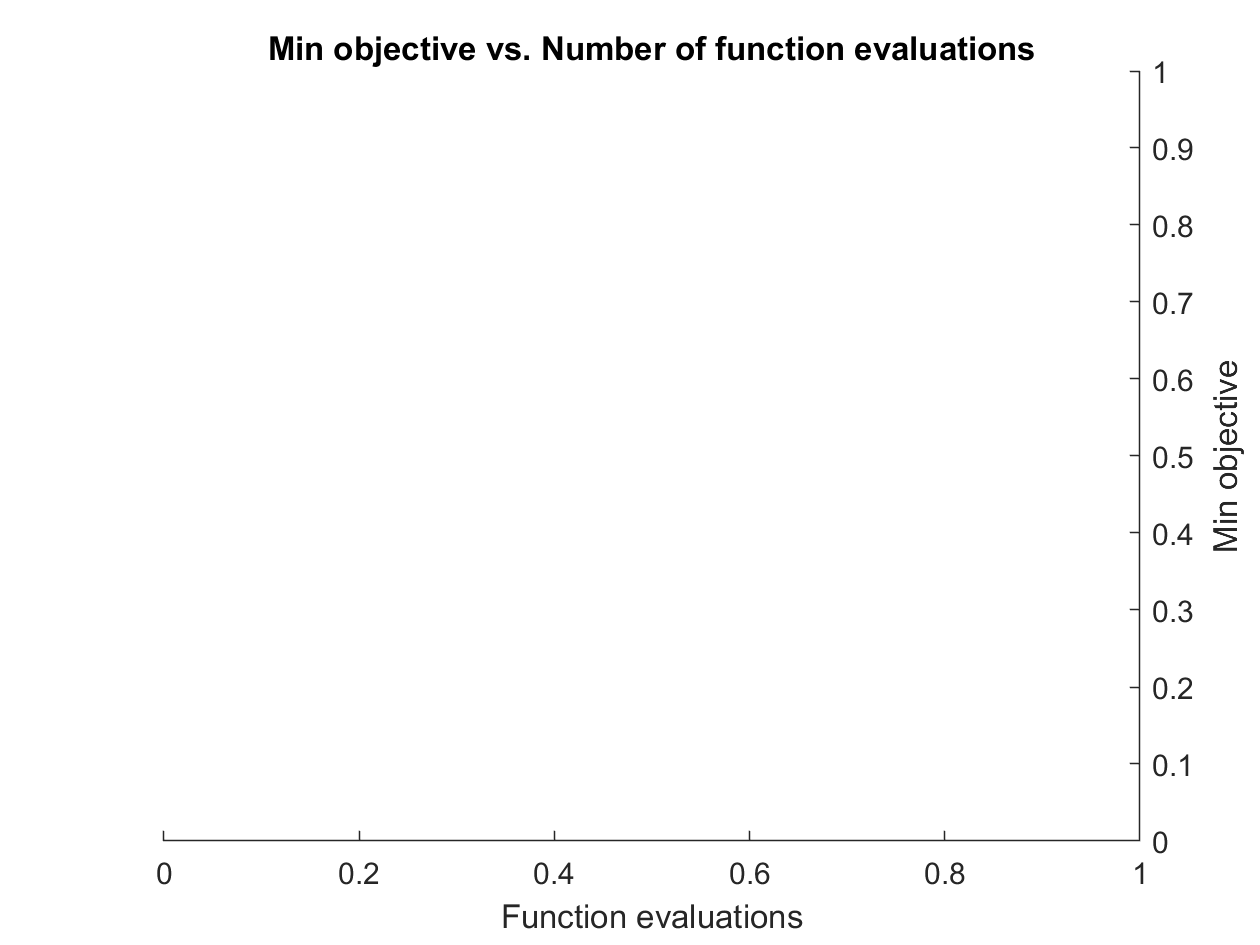

Error using trainNetwork (line 170)
Invalid training data. If the network outputs sequences, then the responses must be a cell array of categorical sequences, or a categorical sequence.

Error in makeObjFcn/valErrorFun (line 30)
    trainedNet = trainNetwork(norm_predictors,train_targetclass,layers, options); %Train the network

Error in 

BayesObject = bayesopt(ObjFcn,optVars, ...
    'MaxTime',14*60*60, ...
    'IsObjectiveDeterministic',false, ...
    'UseParallel',false);

Train the model

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:02 |       32.03% |       22.96% |       1.6021 |       1.6013 |          0.0050 |


|       1 |          50 |       00:00:04 |       60.16% |       57.09% |       1.3024 |       1.3269 |          0.0050 |


|======================================================================================================================|


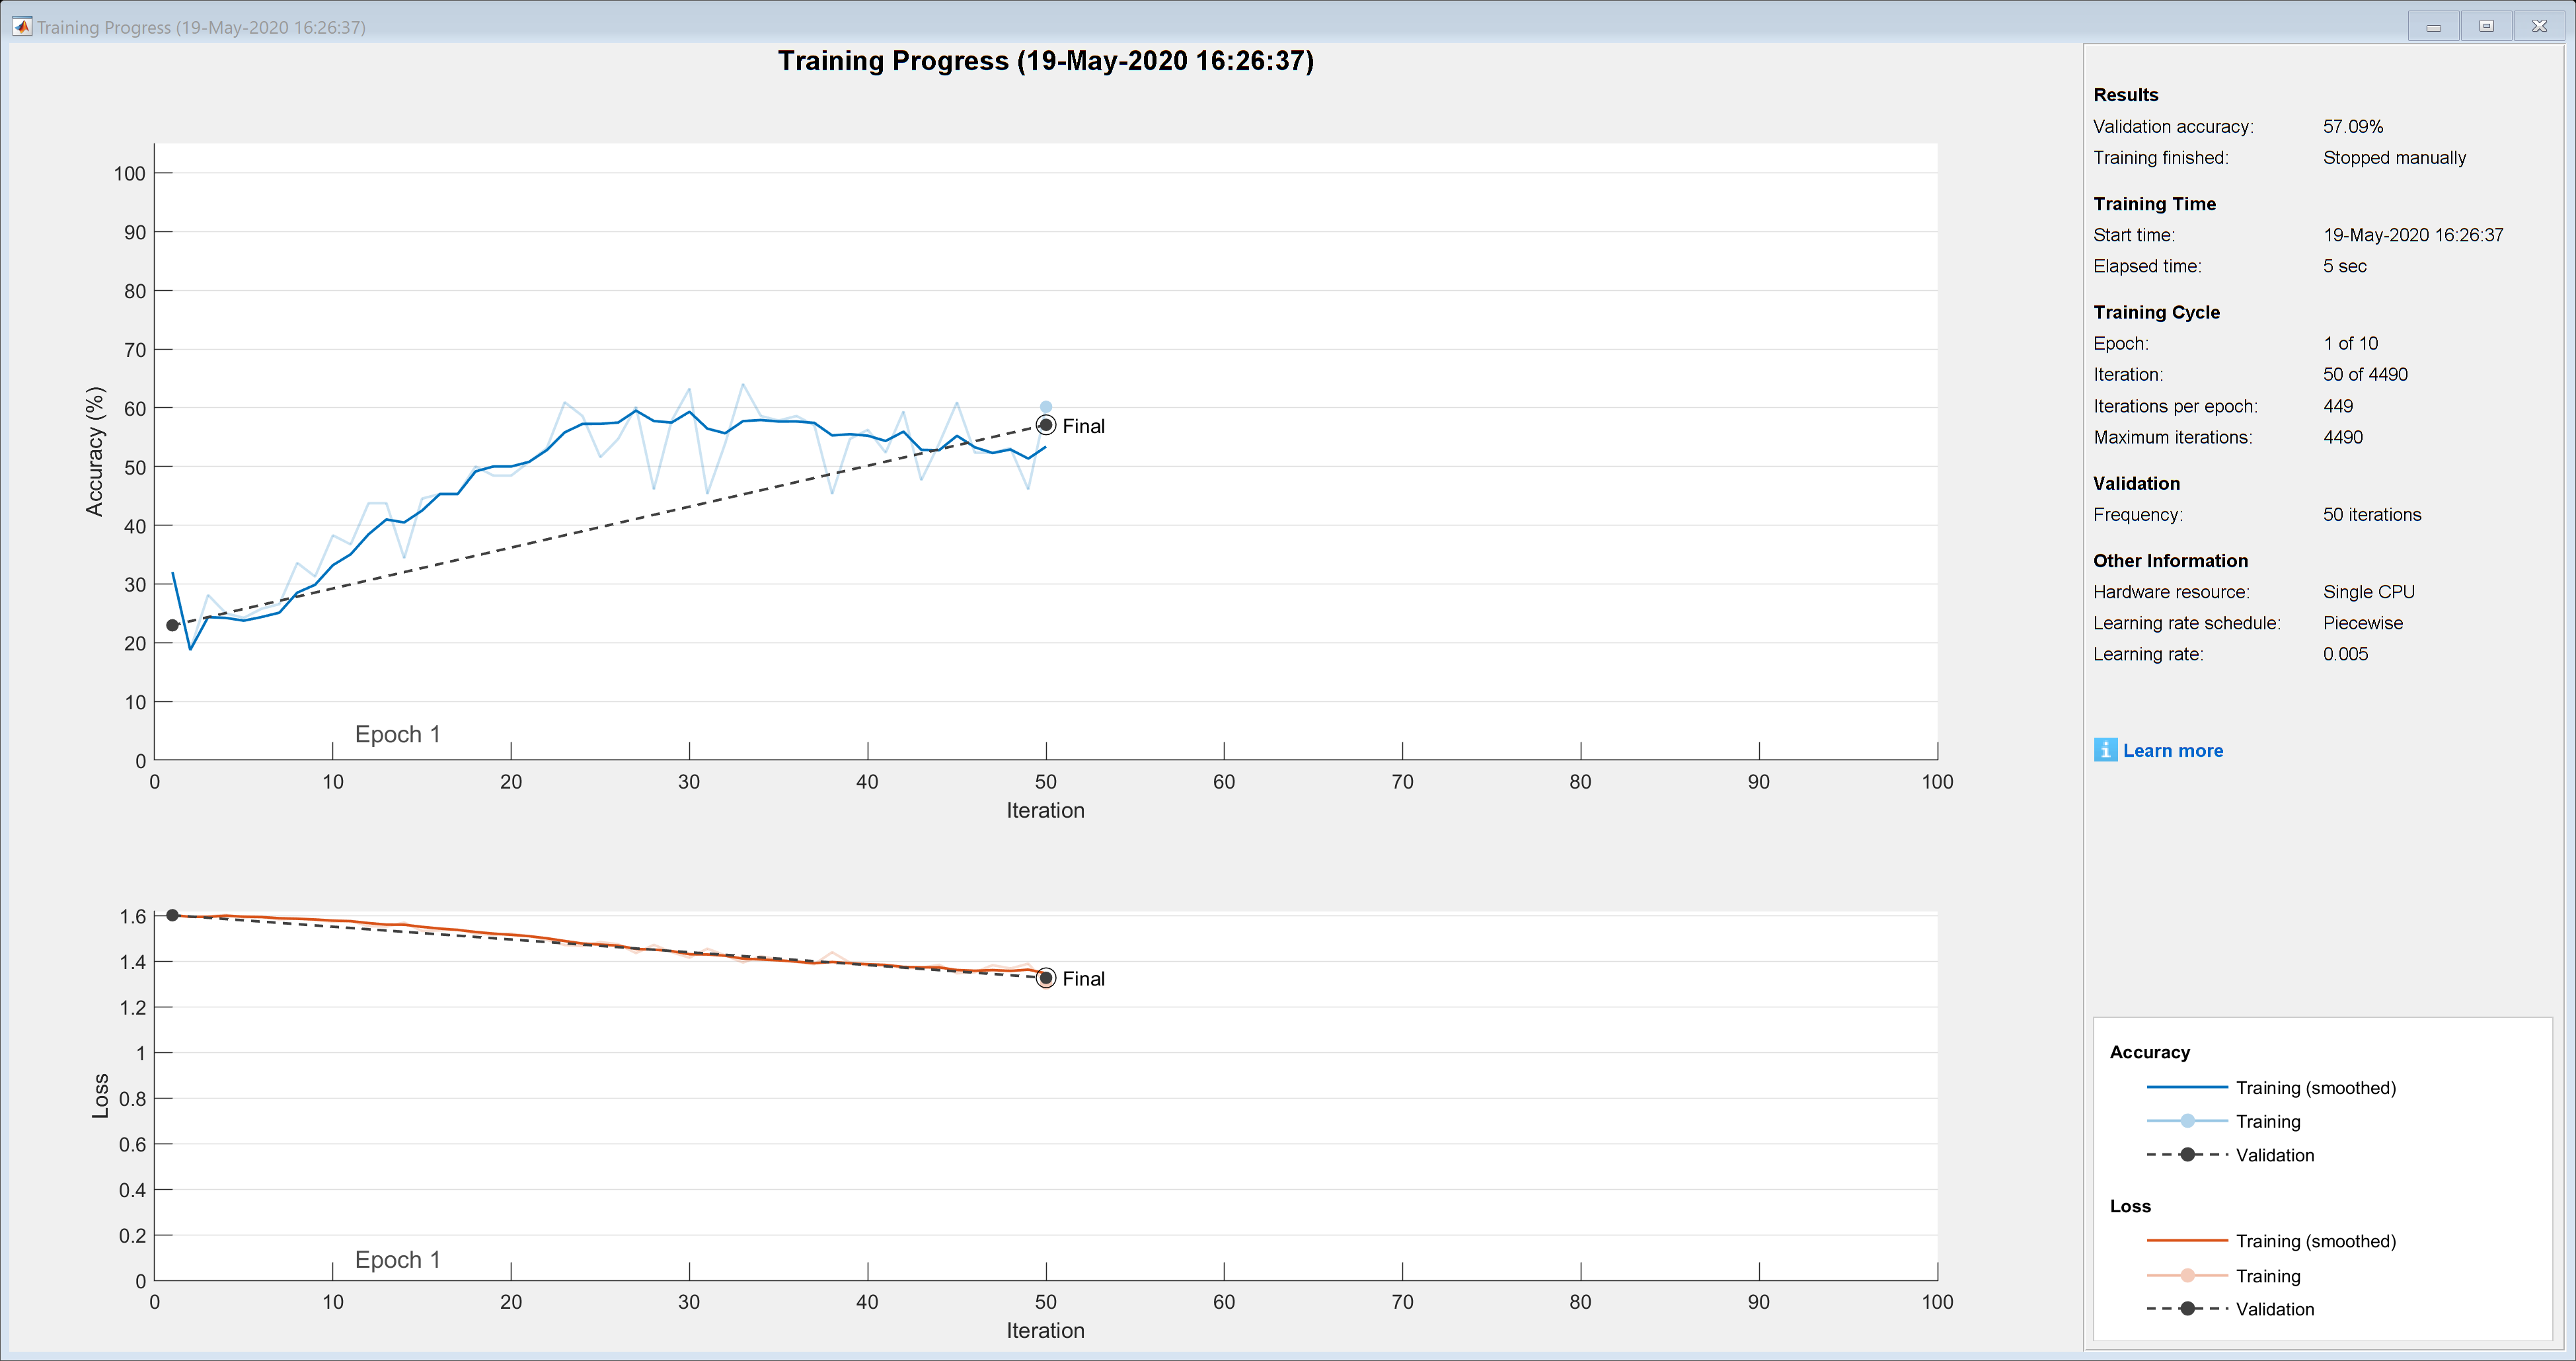



net = trainNetwork(matrixDataTrain, catTarget, layers, options);
sgdmnet = trainNetwork(matrixDataTrain, catTarget, layers_2, optionsSGDM);

rsmpnet = trainNetwork(matrixDataTrain, catTarget, layers, optionsRSMP);

y = net(x);

Unrecognized function or variable 'x'.

perf = crossentropy(net,t,y)

Analyse the training

analyzeNetwork(net)


Run the prediction

transpXTest = transpose(XTest);
[prediction, scores] = classify(net,matrixDataTest);

[predictionSGDM, scoresSGDM] = classify(sgdmnet,matrixDataTest);
[predictionRSMP, scoresRSMP] = classify(rsmpnet,matrixDataTest);


Evaluate the results

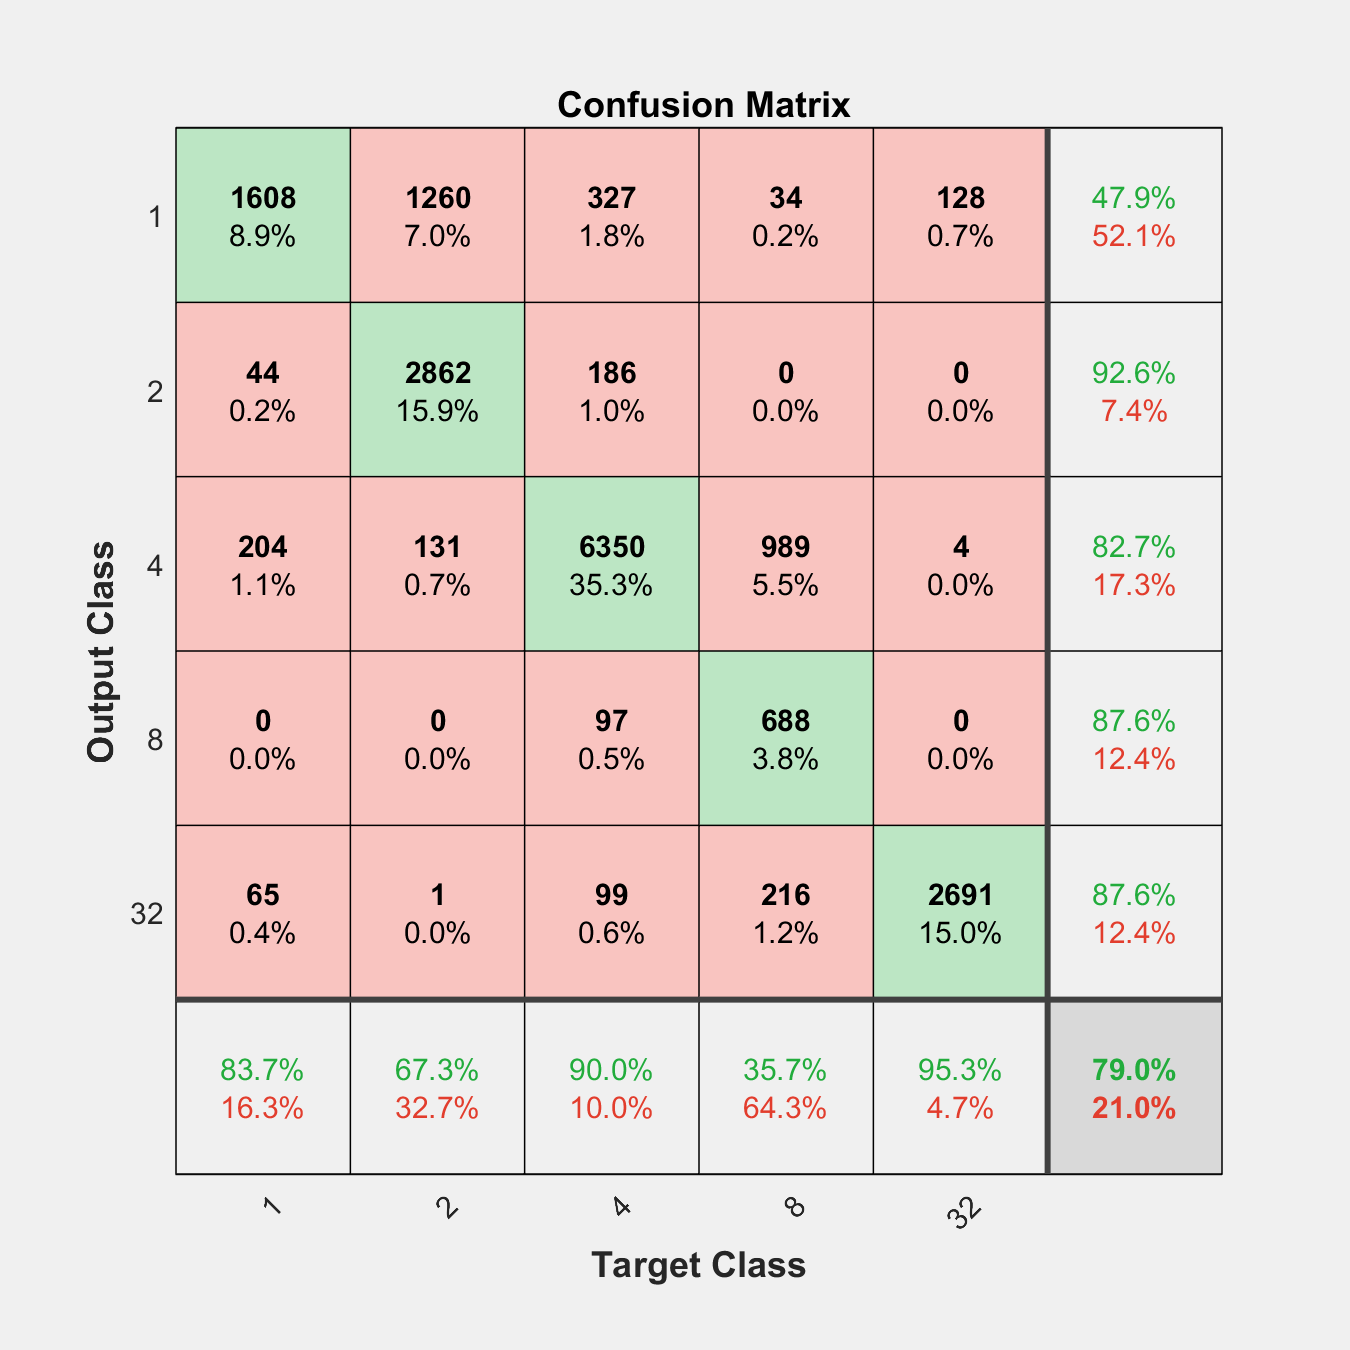

%ADAM
acc = sum(prediction == catTargetTest)./numel(catTargetTest);
[X, Y, T, AUC] = perfcurve(catTargetTest,scores(:,5),1);
ROC_LSTM = AUC;
kappa = cohensKappa(catTargetTest,prediction);
confusionmat(catTargetTest, prediction);
plotconfusion(catTargetTest,prediction);

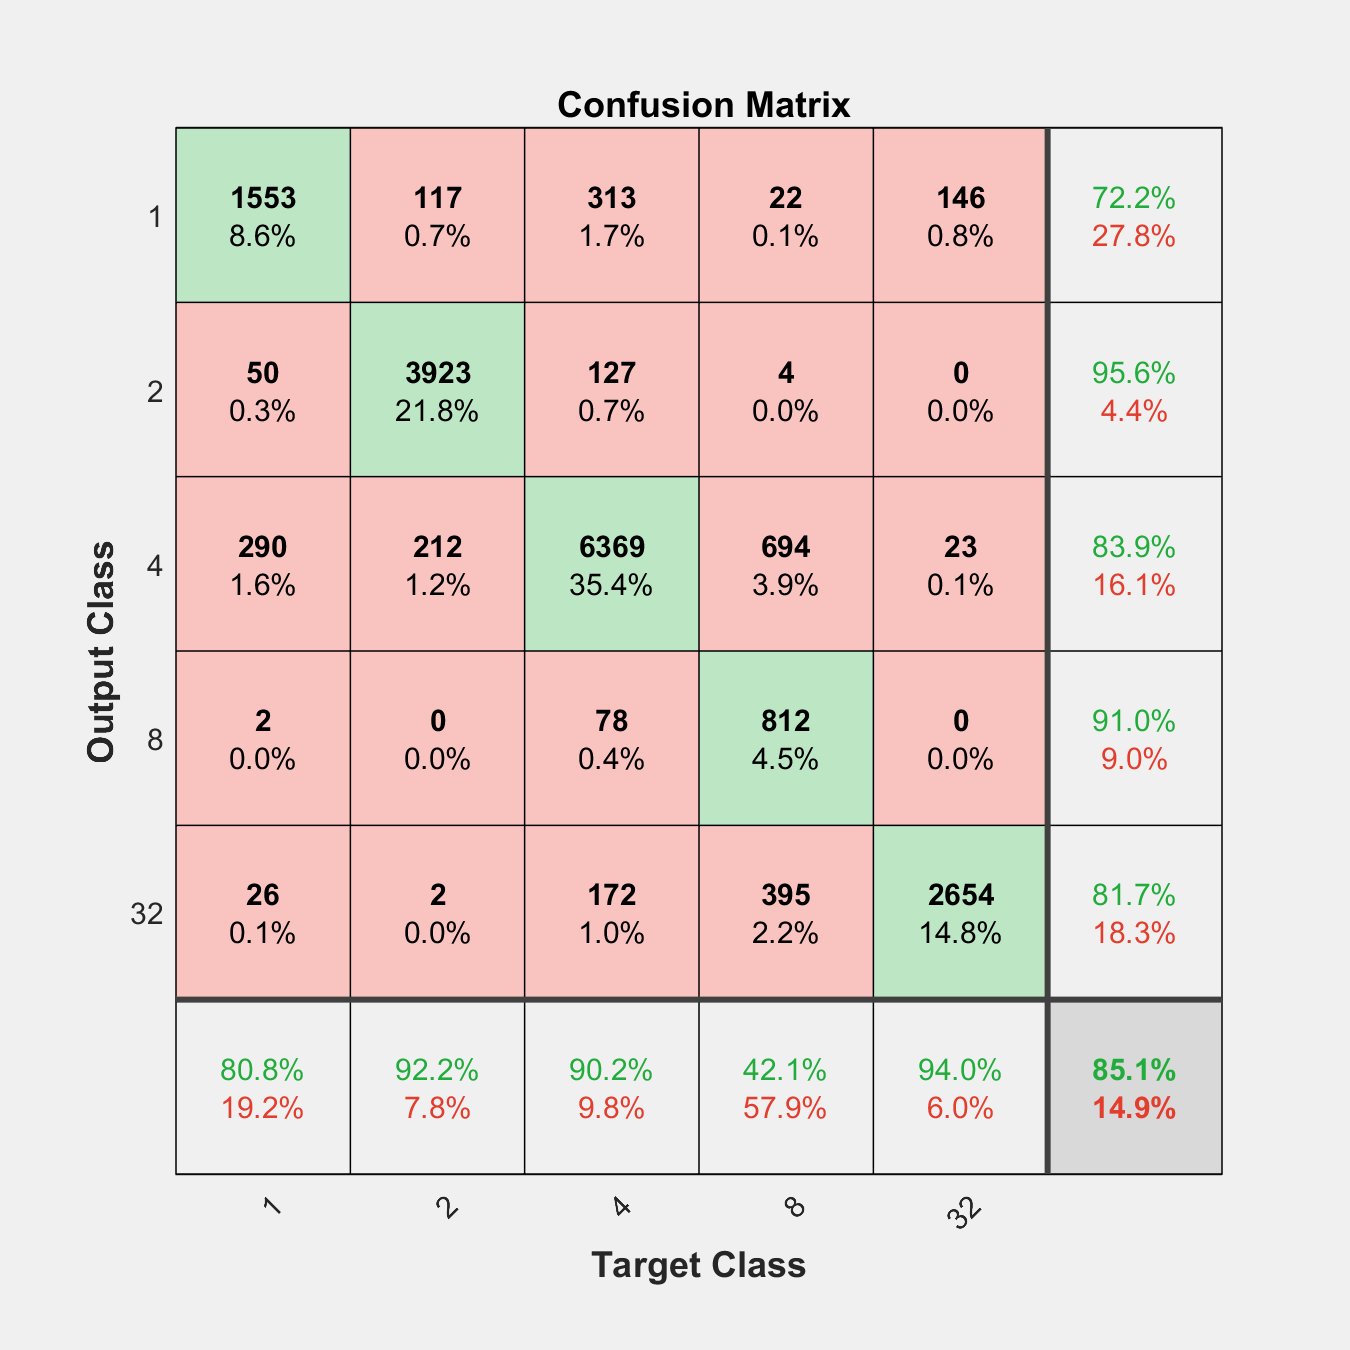


%SGDM
accSGDM = sum(predictionSGDM == catTargetTest)./numel(catTargetTest);
[XSGDM, YSGDM, TSGDM, AUCSGDM] = perfcurve(catTargetTest,scoresSGDM(:,5),1);
ROC_LSTM_SGDM = AUCSGDM;
kappaSGDM = cohensKappa(catTargetTest,predictionSGDM);
confusionmat(catTargetTest, predictionSGDM);
plotconfusion(catTargetTest,predictionSGDM);


%RSMP
accRSMP = sum(predictionRSMP == catTargetTest)./numel(catTargetTest);
[XRSMP, YRSMP, TRSMP, AUCSRSMP] = perfcurve(catTargetTest,scoresRSMP(:,5),1);
ROC_LSTM_RSMP = AUCSRSMP;
kappaRSMP = cohensKappa(catTargetTest,predictionRSMP);
confusionmat(catTargetTest, predictionRSMP);
plotconfusion(catTargetTest,predictionRSMP);
%performance_measures = Evaluate(prediction, catTargetTest);

err = immse(predictionRSMP,catTargetTest)
perf = mse(net, predictionRSMP, catTargetTest, 'regularization', 0.01)